# AP157 - Activity 1

## Activity 1.1 Image DIY

1. Sinusoid along the x-direction with frequency of 4 cycles per cm. 

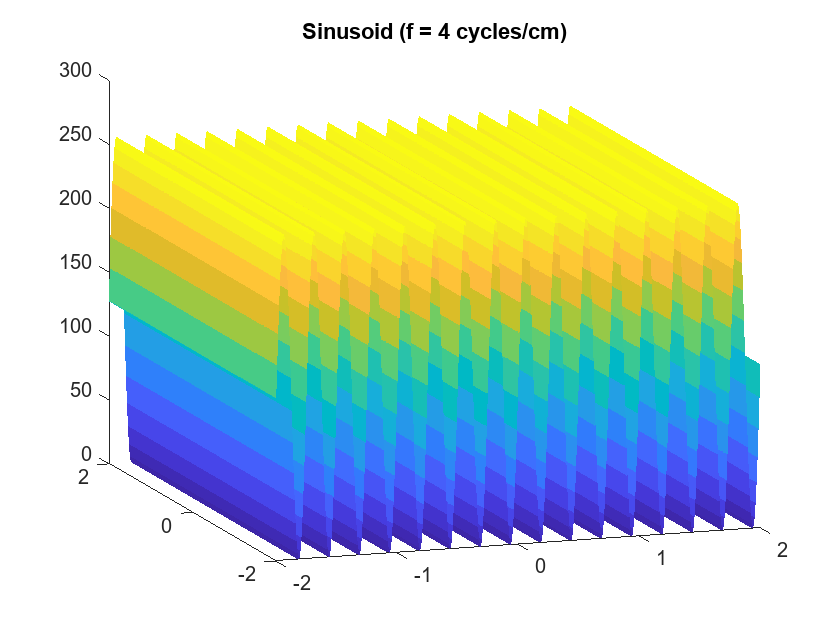

clear
%Sinusoid
N = 500; 
x = linspace(2,-2,N);
y = x;
[X,~] = meshgrid(x,y);
A = 2;
f = 4;
omega = 2*pi*f;
R = A*sin(omega.*X);
A = rescale(R,0,255);
mesh(x,y,A, 'FaceAlpha', '0.5');
title("Sinusoid (f = 4 cycles/cm)");                                                                                                                                                                                                                                       
view([-19 15]);
grid off;
saveas(gcf, "Sinusoid.tif");

2. Grating, frequency is 5 line pairs per cm.

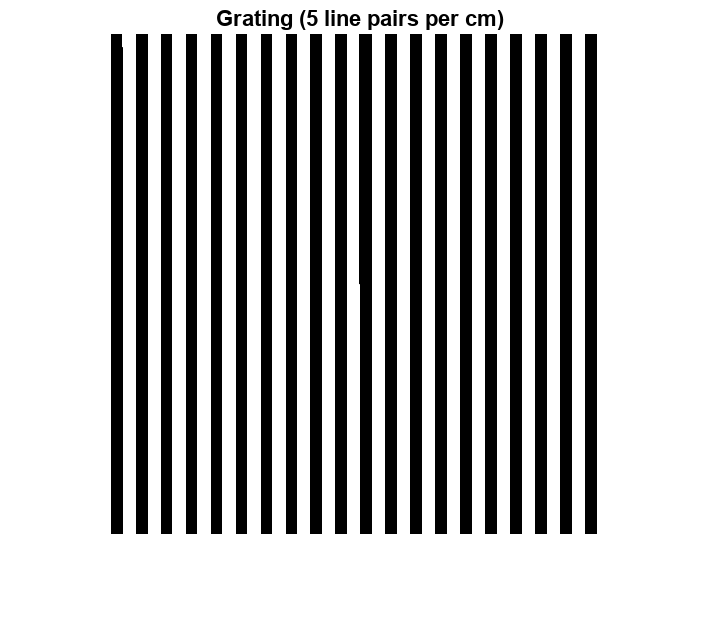

N = 500;
x = linspace(-2,2,N);
y = x;
[X,~] = meshgrid(x,y);
a = 5;
omega = 2*pi*a;
R = sin(omega.*X);
A = zeros(size(R));
A(R<0.1) = 1;
%image 
imshow(A);
title("Grating (5 line pairs per cm)");
saveas(gcf,'grating.tif');

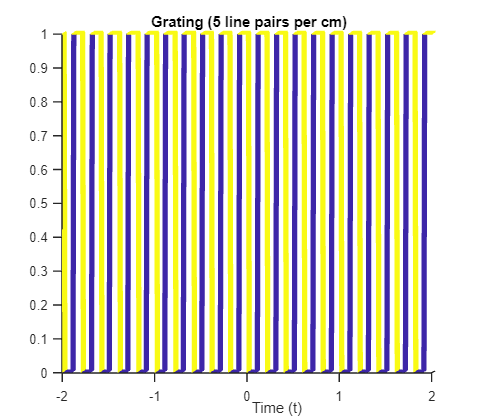

%square wave
mesh(x,y,A);
title("Grating (5 line pairs per cm)");
view([0.600 0.444])
grid off;
ylabel("Amplitude (A)");
xlabel("Time (t)"); 

3. Hubble's Primary Mirror - Circle with a hole in the middle (Annulus)

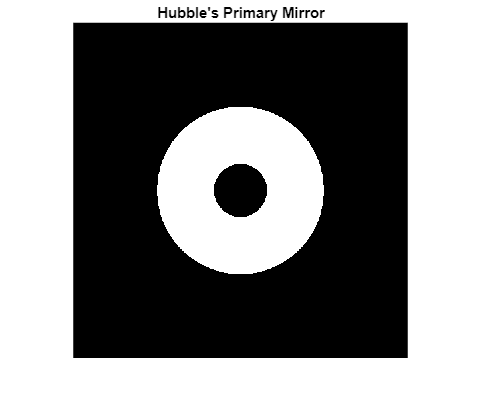

%annulus
N = 500; 
x = linspace(-2, 2, N);
y =x;
[X,Y] = meshgrid(x,y);
R = (X.^2 + Y.^2);
A = zeros(size(R));
A(R<1) = 1;
A(R<0.1) = 0;
imshow(A);
title("Hubble's Primary Mirror");

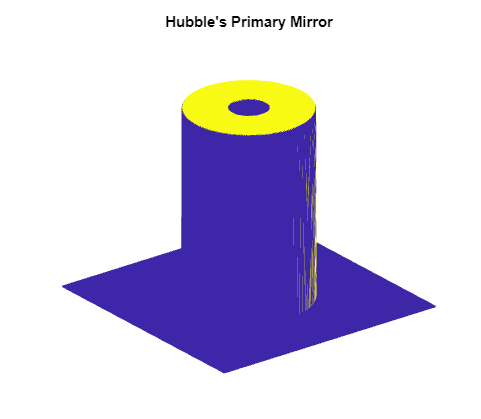

mesh(x,y,A);
axis off;
title("Hubble's Primary Mirror")

4. Hexagon Array (James Webb Space Telescope)

Note: I used the nsidedpoly function which returns n-sided polygon with n equal-length sides. 

Syntax: hex1 = nsidedpoly(no. of sides, "Center", [x0,y0], "Sidelength", L)

Total number of hexagons: 18 

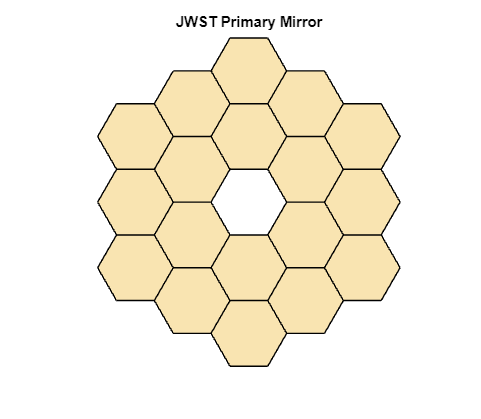

%hexagon array
hex1 = nsidedpoly(6, "Center", [0,0], "SideLength", 1);
hex2 = nsidedpoly(6, "Center", [1.5,0.866025], "SideLength", 1);
hex3 = nsidedpoly(6, "Center", [-1.5,0.866025], "SideLength", 1);
hex4 = nsidedpoly(6, "Center", [-1.5,0.866025+1.73205], "SideLength", 1);
hex5 = nsidedpoly(6, "Center", [1.5,0.866025+1.73205], "SideLength", 1);
hex6 = nsidedpoly(6, "Center", [0,3.4641], "SideLength", 1);
hex7 = nsidedpoly(6, "Center", [3,1.73205], "SideLength", 1);
hex8 = nsidedpoly(6, "Center", [-3,1.73205],"SideLength", 1);
hex9 = nsidedpoly(6, "Center", [-3,1.73205*2],"SideLength", 1);
hex10 = nsidedpoly(6, "Center", [3,1.73205*2],"SideLength", 1);
hex11 = nsidedpoly(6, "Center", [-3,1.73205-0.866025*2],"SideLength", 1);
hex12 = nsidedpoly(6, "Center", [3,1.73205-0.866025*2],"SideLength", 1);
hex13 = nsidedpoly(6, "Center", [1.5,-0.866025], "SideLength", 1);
hex14 = nsidedpoly(6, "Center", [-1.5,-0.866025], "SideLength", 1);
hex15 = nsidedpoly(6, "Center", [-1.5,4.33013], "SideLength", 1);
hex16 = nsidedpoly(6, "Center", [1.5,4.33013], "SideLength", 1);
hex17 = nsidedpoly(6, "Center", [0,5.19616], "SideLength", 1);
hex18 = nsidedpoly(6, "Center", [0,-1.73205], "SideLength", 1);
r = plot([hex1, hex2, hex3, hex4,hex5, hex6, hex7, hex8,hex9, hex10, hex11, hex12, hex13, hex14, hex15, hex16, hex17, hex18]);
for i = 1:1:18
    r(i).FaceColor ="#EDB120";
    axis off;
    axis equal;
    title('JWST Primary Mirror');
end 
saveas(gcf, 'hexagon.tif');

## Activity 1.2. Color Image 

Here I tried to simulate the code in the module. 

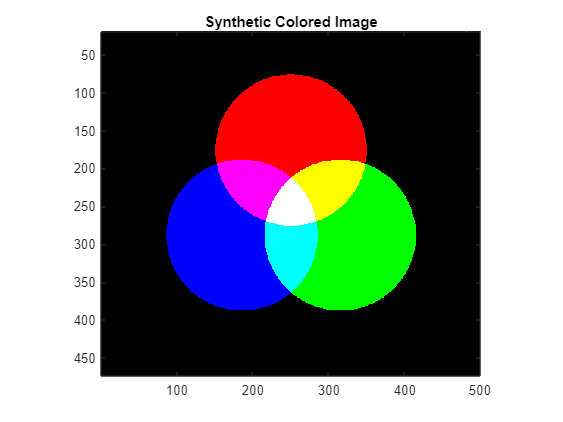

clear; close all;
N = 500;
x = linspace(-10,10,N);
y = x;
[X,Y] = meshgrid(x,y);
Rd = zeros(N,N);
Gn = Rd; Bl = Rd;
%draw colored circles
Rt = 3; RC = 4; deg = 30;
xt = Rt*cosd(deg); yt=Rt*sind(deg);
R = sqrt((X.^2) + (Y+Rt).^2);
Rd(R<RC) = 1;
R = sqrt((X-xt).^2 + (Y-yt).^2);
Gn(R<RC) = 1;
R = sqrt((X+xt).^2 + (Y-yt).^2);
Bl(R<RC) = 1;
I(:,:,1) = Rd;
I(:,:,2) = Gn;
I(:,:,3) = Bl;
figure;image(I); 
axis equal;
title('Synthetic Colored Image');

Mathematically recreate the Olympics logo as an image.

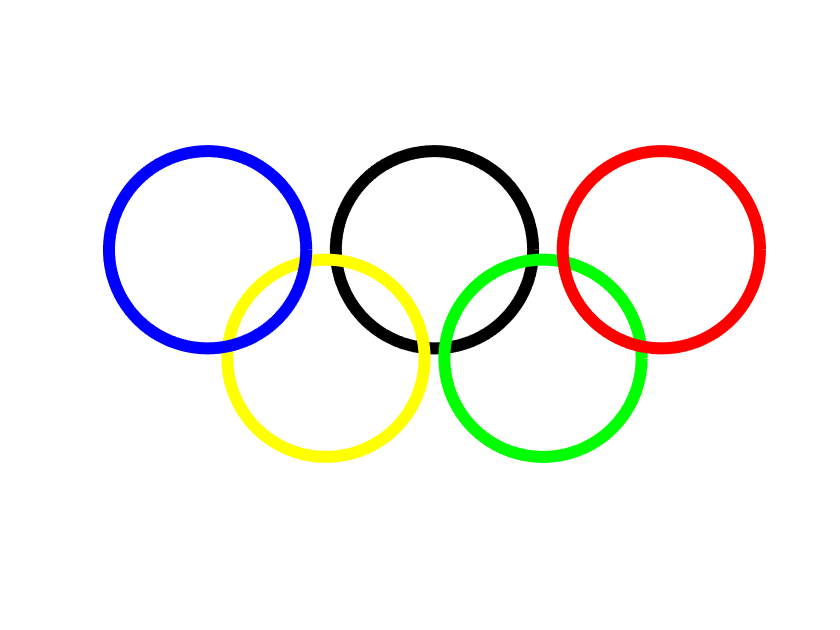

clear
a = linspace(0,2*pi);
%black ring
x = cos(a);
y = sin(a);
%yellow ring
x1 = cos(a) - 1.1;
y1 = sin(a) - 1.1;
%green ring
x2 = cos(a) + 1.1;
y2 = sin(a) - 1.1;
%red ring 
x3 = cos(a) + 2.3;
y3 = sin(a);
%blue ring
x4 = cos(a) - 2.3;
y4 = sin(a);
%plotting
plot(x,y,"LineWidth",6, "Color", "k");
hold on;
plot(x1,y1, "LineWidth", 6, "Color", "y");
plot(x2,y2, "LineWidth", 6, "Color", "g");
plot(x3,y3, "LineWidth", 6, "Color", "r");
plot(x4,y4, "LineWidth", 6, "Color", "b");
axis equal;
axis off;
hold off;
%saving image in different file format
saveas(gcf, "OlympicRings.png");
saveas(gcf, "OlympicRings.jpg");
saveas(gcf, "OlympicRings.tif");
saveas(gcf, "OlympicRings", "bmp")

## Activity 1.3. Altering the Input-Output Curve

Activity 1.3 was done in GIMP. No codes here. 

## Activity 1.4. Histogram Backprojection on Grayscale Images

- Open your dark-looking image and convert to grayscale.

clear
Igray = rgb2gray(imread("janensunset.tif"));

2. Obtain the grayscale histogram of the image and normalize by the number of pixel to get its PDF.

PDF = hist(Igray(:), (0:255))/numel(Igray); 
CDF = cumsum(PDF); 

3. Create a CDF function of a uniform distribution with x values equal to 0 to 255 and y equals 0 to 1. Use histogram backprojection to pixel-per-pixel backproject the image pixel values by finding its corresponding y-value in the desired CDF. That is, replace the dark pixel values with the x-values from the c

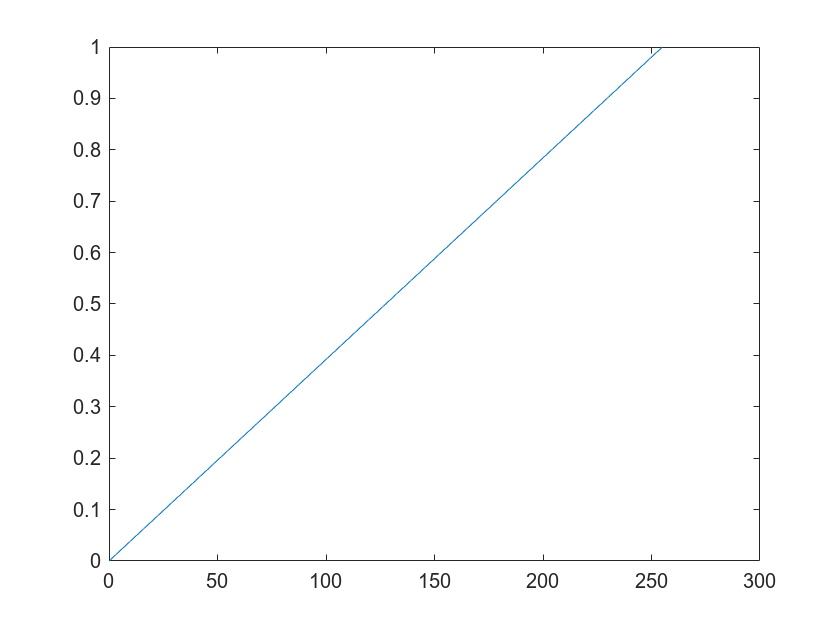

x = 0:255;
desiredCDF = (1/255)*x;
newGS = interp1(desiredCDF,x,CDF(Igray(:)+1));
Igraynew = reshape(newGS, size(Igray));
figure; plot(0:255, desiredCDF);

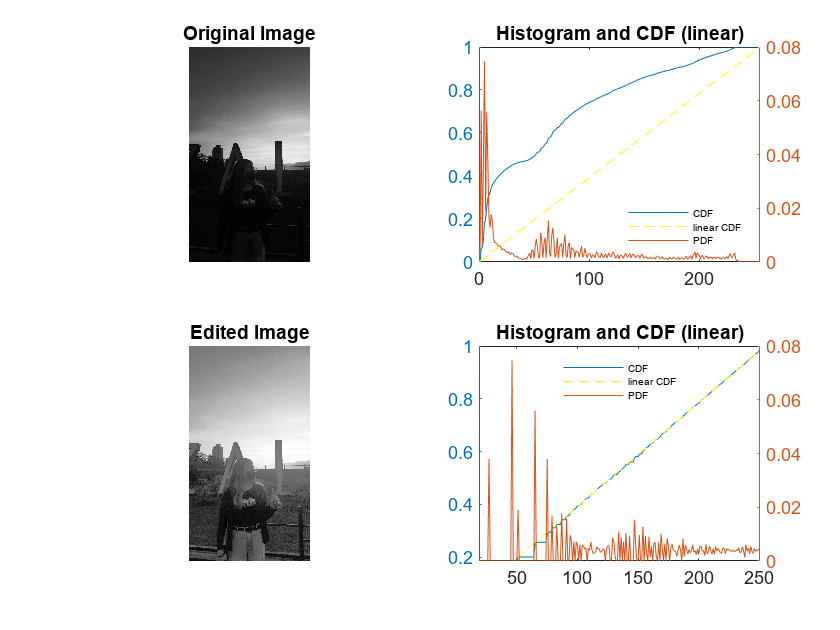

PDFnew = hist(Igraynew(:), 0:255)/numel(Igraynew);
CDFnew = cumsum(PDFnew);

subplot(2,2,1);
imshow(Igray);
title('Original Image');

subplot(2,2,2);
yyaxis right; plot(0:255, PDF);
hold on;
yyaxis left; plot((0:255), CDF); plot(0:255, desiredCDF, 'y--');
title("Histogram and CDF (linear)");
legend('CDF', 'linear CDF', 'PDF', 'Location', 'southeast', 'fontsize', 5);
legend('boxoff');
xlim([0 255]);
hold off;

subplot(2,2,3);
imshow(uint8(Igraynew));
title('Edited Image');

subplot(2,2,4);
yyaxis right; plot(0:255, PDFnew); 
hold on;
yyaxis left; plot((0:255), CDFnew); plot(0:255, desiredCDF, 'y--');
title("Histogram and CDF (linear)");
legend('CDF', 'linear CDF', 'PDF', 'Location', 'north', 'fontsize', 5);
legend('boxoff');
xlim([0 255]);
hold off;   

Non-linear CDF

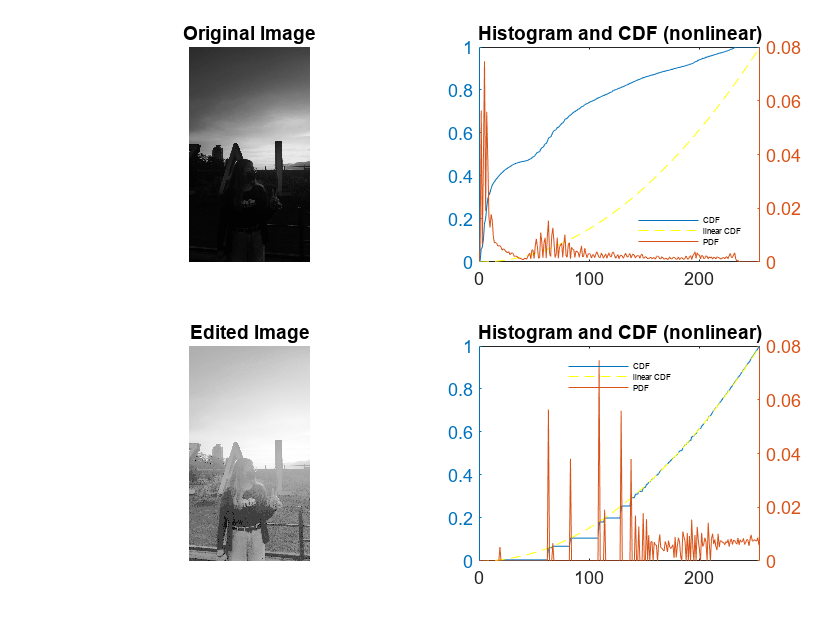

clear; close all; 
Igray = rgb2gray(imread("janensunset.tif"));
PDF = hist(Igray(:), (0:255))/numel(Igray); 
CDF = cumsum(PDF); 
x = 0:255;
desiredCDF1 = (1/255)^2*x.^2;
newGS1 = interp1(desiredCDF1,x,CDF(Igray(:)+1));
Igraynew1 = reshape(newGS1, size(Igray));
PDFnew1 = hist(Igraynew1(:), 0:255)/numel(Igraynew1);
CDFnew1 = cumsum(PDFnew1);

%plotting
subplot(2,2,1);
imshow(Igray);
title('Original Image');

subplot(2,2,2);
yyaxis right; plot(0:255, PDF);
hold on;
yyaxis left; plot((0:255), CDF); plot(0:255, desiredCDF1, 'y--');
title("Histogram and CDF (nonlinear)");
legend('CDF', 'linear CDF', 'PDF', 'Location', 'southeast', 'fontsize', 4);
legend('boxoff');
xlim([0 255]);
hold off;

subplot(2,2,3);
imshow(uint8(Igraynew1));
title('Edited Image');

subplot(2,2,4);
yyaxis right; plot(0:255, PDFnew1);
hold on;
yyaxis left; plot((0:255), CDFnew1); plot(0:255, desiredCDF1, 'y--');
title("Histogram and CDF (nonlinear)")
legend('CDF', 'linear CDF', 'PDF', 'Location', 'north', 'fontsize', 4);
legend('boxoff');
xlim([0 255]);
hold off;   

Nonlinear CDF (anader wan)

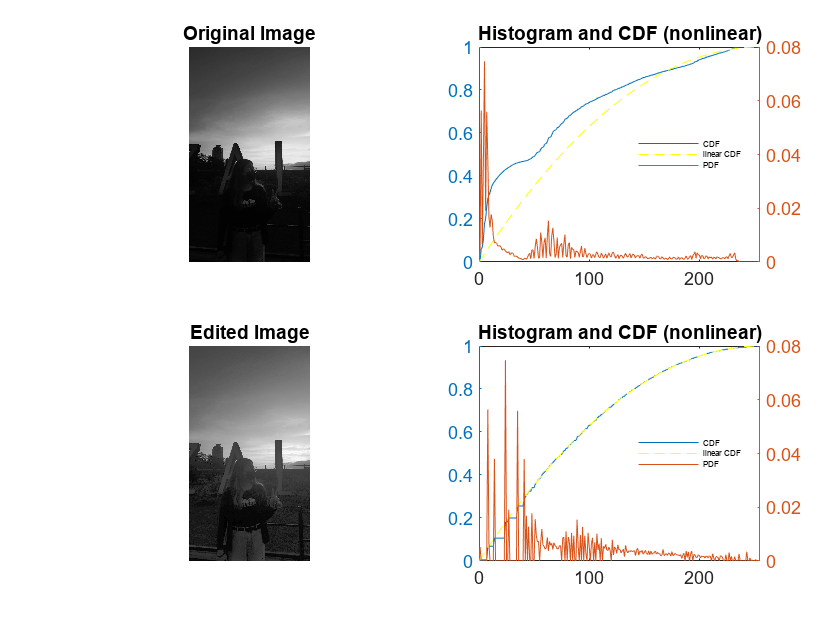

%new 
clear; close all;
Igray = rgb2gray(imread("janensunset.tif"));
PDF = hist(Igray(:), (0:255))/numel(Igray); 
CDF = cumsum(PDF); 
x = 0:255;
desiredCDF2 = -(1/255)^2*(x-255).^2 + 1;
newGS1 = interp1(desiredCDF2,x,CDF(Igray(:)+1));
Igraynew2 = reshape(newGS1, size(Igray));
PDFnew2 = hist(Igraynew2(:), 0:255)/numel(Igraynew2);
CDFnew2 = cumsum(PDFnew2);

subplot(2,2,1);
imshow(Igray);
title('Original Image');

subplot(2,2,2);
yyaxis right; plot(0:255, PDF);
hold on;
yyaxis left; plot((0:255), CDF); plot(0:255, desiredCDF2, 'y--');
title("Histogram and CDF (nonlinear)");
legend('CDF', 'linear CDF', 'PDF', 'Location', 'east', 'fontsize', 4);
legend('boxoff');
xlim([0 255]);
hold off;

subplot(2,2,3);
imshow(uint8(Igraynew2));
title('Edited Image');

subplot(2,2,4);
yyaxis right; plot(0:255, PDFnew2);
hold on;
yyaxis left; plot((0:255), CDFnew2); plot(0:255, desiredCDF2, 'y--'); 
title("Histogram and CDF (nonlinear)")
legend('CDF', 'linear CDF', 'PDF', 'Location', 'east', 'fontsize', 4);
legend('boxoff');
xlim([0 255]);
hold off;   

## Activity 1.5. Contrast Enhancement

Contrast stretching by using the given equation. Here, I used different percentiles: 10, 50, and 90. 

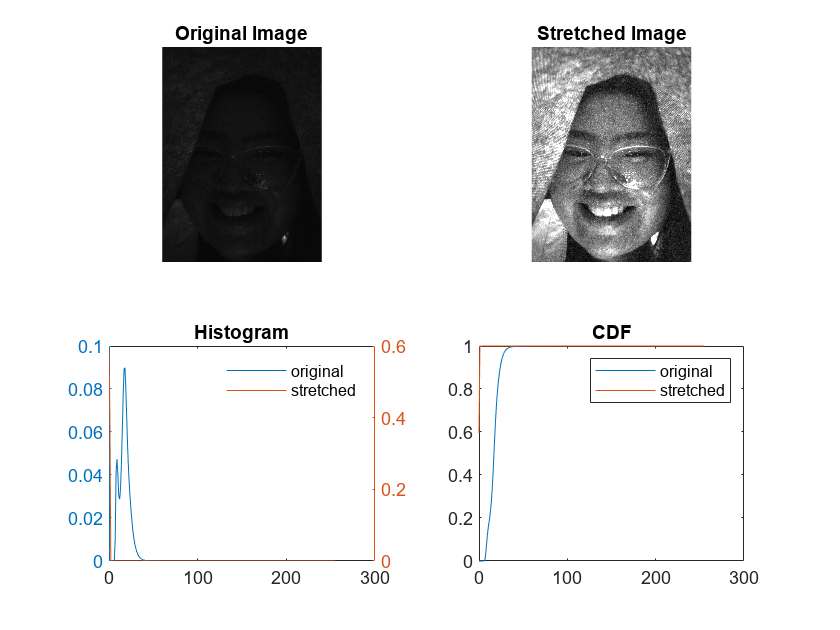

%prctile = 10
clear; close all;
Igray = rgb2gray(imread("JanenSelfie.jpg"));
PDF = hist(Igray(:), (0:255), 'b')/numel(Igray); 
CDF = cumsum(PDF); 
Iold = double(Igray);
Gray_min = double(min(Igray));
P_min = prctile(Gray_min, 10);
Gray_max = double(max(Igray));
P_max = prctile(Gray_max, 10);
Icontrast = ((Iold - P_min)./(P_max - P_min));
PDFnew = hist(Icontrast(:), (0:255))/numel(Icontrast);
CDFnew = cumsum(PDFnew); 

%plotting 
subplot(2,2,1);
imshow(Igray);
title('Original Image');

subplot(2,2,2);
imshow(Icontrast);
title('Stretched Image');

subplot(2,2,3);
yyaxis left; plot(0:255, PDF);
hold on;
yyaxis right; plot(0:255, PDFnew);
title('Histogram');
legend('original', 'stretched');
legend('boxoff');
hold off;
subplot(2,2,4);
plot(0:255, CDF);
hold on;
plot(0:255, CDFnew);
hold off;
title('CDF');
legend('original', 'stretched');

50th Percentile

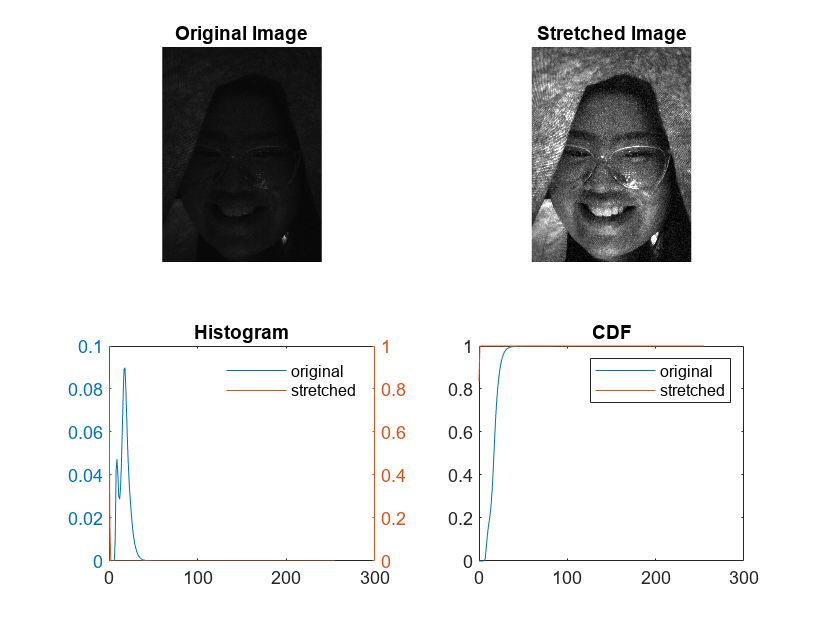

clear; close all;
Igray = rgb2gray(imread("JanenSelfie.tif"));
PDF = hist(Igray(:), (0:255), 'b')/numel(Igray); 
CDF = cumsum(PDF); 
Iold = double(Igray);
Gray_min = double(min(Igray));
P_min = prctile(Gray_min, 50);
Gray_max = double(max(Igray));
P_max = prctile(Gray_max, 50);
Icontrast = ((Iold - P_min)./(P_max - P_min));
PDFnew = hist(Icontrast(:), (0:255))/numel(Icontrast);
CDFnew = cumsum(PDFnew); 
%plotting 
subplot(2,2,1);
imshow(Igray);
title('Original Image');

subplot(2,2,2);
imshow(Icontrast);
title('Stretched Image');

subplot(2,2,3);
yyaxis left; plot(0:255, PDF);
hold on;
yyaxis right; plot(0:255, PDFnew);
title('Histogram');
legend('original', 'stretched');
legend('boxoff');
hold off;

subplot(2,2,4);
plot(0:255, CDF);
hold on;
plot(0:255, CDFnew);
hold off;
title('CDF');
legend('original', 'stretched');

90th Percentile

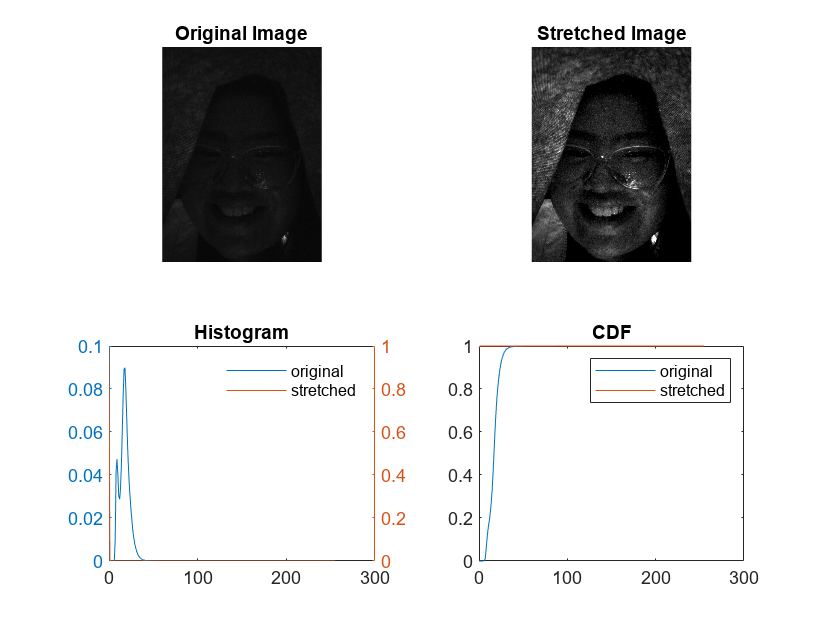

clear; close all;
Igray = rgb2gray(imread("JanenSelfie.tif"));
PDF = hist(Igray(:), (0:255), 'b')/numel(Igray); 
CDF = cumsum(PDF); 
Iold = double(Igray);
Gray_min = double(min(Igray));
P_min = prctile(Gray_min, 90);
Gray_max = double(max(Igray));
P_max = prctile(Gray_max, 90);
Icontrast = ((Iold - P_min)./(P_max - P_min));
PDFnew = hist(Icontrast(:), (0:255))/numel(Icontrast);
CDFnew = cumsum(PDFnew); 
%plotting 
subplot(2,2,1);
imshow(Igray);
title('Original Image');

subplot(2,2,2);
imshow(Icontrast);
title('Stretched Image');

subplot(2,2,3);
yyaxis left; plot(0:255, PDF);
hold on;
yyaxis right; plot(0:255, PDFnew);
title('Histogram');
legend('original', 'stretched');
legend('boxoff');
hold off;
subplot(2,2,4);
plot(0:255, CDF);
hold on;
plot(0:255, CDFnew);
hold off;
title('CDF');
legend('original', 'stretched');

I just tried what will happen if I don't use percentiles. Here, there are visible lines in the image (not a good sign ick).

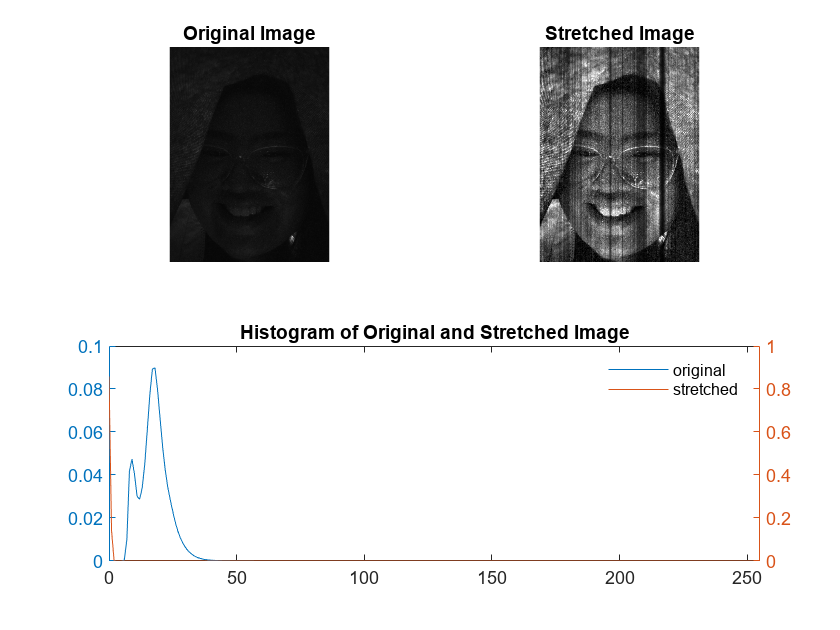

clear; close all;
Igray = rgb2gray(imread("JanenSelfie.tif"));
PDF = hist(Igray(:), (0:255), 'b')/numel(Igray); 
CDF = cumsum(PDF); 
Iold = double(Igray);
Gray_min = double(min(Igray));
%P_min = prctile(Gray_min, 10);
Gray_max = double(max(Igray));
%P_max = prctile(Gray_max, 10);
Icontrast = ((Iold - Gray_min)./(Gray_max - Gray_min));
PDFnew = hist(Icontrast(:), (0:255))/numel(Icontrast);
CDFnew = cumsum(PDFnew); 
%plotting 
subplot(2,2,1);
imshow(Igray);
title('Original Image');

subplot(2,2,2);
imshow(Icontrast);
title('Stretched Image');

subplot(2,2,3:4);
yyaxis left; plot(0:255, PDF);
hold on;
yyaxis right; plot(0:255, PDFnew);
title('Histogram of Original and Stretched Image');
legend('original', 'stretched');
legend('boxoff');
xlim([0 255]);
hold off;

## Activity 1.6. Restoring Faded Color Photographs

First part: Contrast Stretching in RGB. 

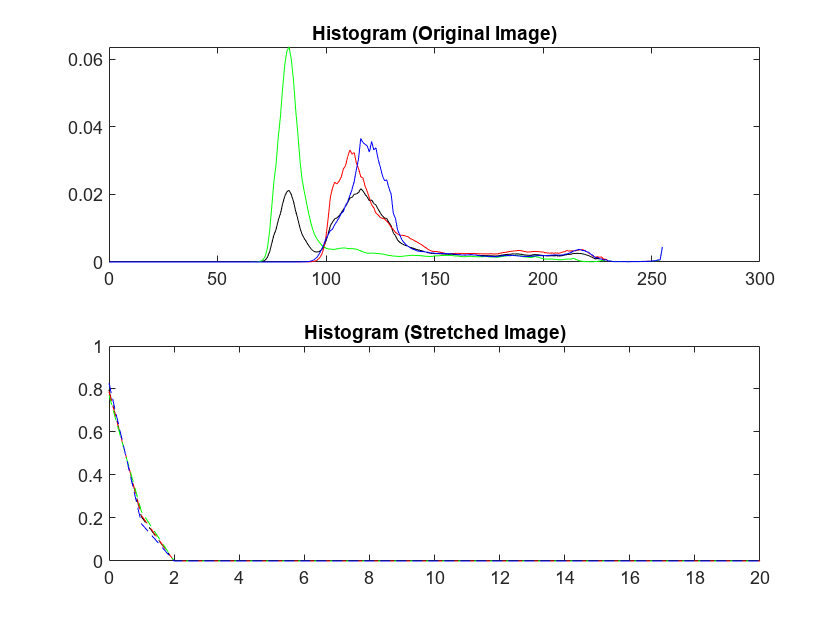

clear; close all;
I = imread("janen.jpg");
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);

%stretch red
Rold = double(R);
Rmin = double(min(R));
Pmin1 = prctile(Rmin, 10);
Rmax = double(max(R));
Pmax1 = prctile(Rmax, 10);
Rcontrast = ((Rold - Pmin1)./(Pmax1 - Pmin1));

%stretch green
Gold = double(G);
Gmin = double(min(G));
Pmin2 = prctile(Gmin, 10);
Gmax = double(max(G));
Pmax2 = prctile(Gmax, 10);
Gcontrast = ((Rold - Pmin2)./(Pmax2 - Pmin2));

%stretch blue
Bold = double(B);
Bmin = double(min(B));
Pmin3 = prctile(Bmin, 10);
Bmax = double(max(B));
Pmax3 = prctile(Bmax, 10);
Bcontrast = ((Bold - Pmin3)./(Pmax3 - Pmin3));

%combining stretched channels
I_restored(:,:,1) = Rcontrast;
I_restored(:,:,2) = Gcontrast;
I_restored(:,:,3) = Bcontrast;


%plotting 
PDF = hist(I(:), (0:255))/numel(I); 
CDF = cumsum(PDF); 
PDFr = hist(R(:), (0:255))/numel(R); 
CDFr = cumsum(PDFr); 
PDFg = hist(G(:), (0:255))/numel(G); 
CDFg = cumsum(PDFg);
PDFb = hist(B(:), (0:255))/numel(B); 
CDFb = cumsum(PDFb); 

PDF1 = hist(I_restored(:), (0:255))/numel(I_restored); 
CDF1 = cumsum(PDF1); 
PDFr1 = hist(Rcontrast(:), (0:255))/numel(Rcontrast); 
CDFr1 = cumsum(PDFr1); 
PDFg1 = hist(Gcontrast(:), (0:255))/numel(Gcontrast); 
CDFg1 = cumsum(PDFg1);
PDFb1 = hist(Bcontrast(:), (0:255))/numel(Bcontrast); 
CDFb1 = cumsum(PDFb1); 

subplot(2,1,1);
plot(0:255, PDF, 'k');
hold on;
plot(0:255, PDFr, 'r');
plot(0:255, PDFg, 'g');
plot(0:255, PDFb, 'b');
title('Histogram (Original Image)')
hold off;
subplot(2,1,2);
plot(0:255, PDF1, 'k--');
hold on;
plot(0:255, PDFr1, 'r--');
plot(0:255, PDFg1, 'g--');
plot(0:255, PDFb1, 'b--');
xlim([0 20]);
title('Histogram (Stretched Image)')
hold off;

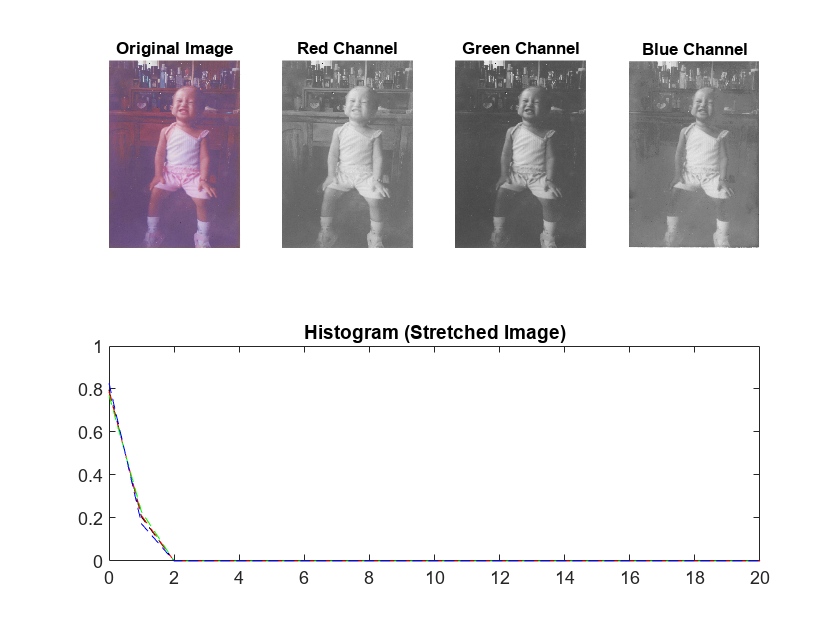

%plotting
subplot(2,4,1);
imshow(I);
title('Original Image');
subplot(2,4,2);
imshow(R);
title('Red Channel');
subplot(2,4,3);
imshow(G);
title('Green Channel');
subplot(2,4,4);
imshow(B);
title('Blue Channel');

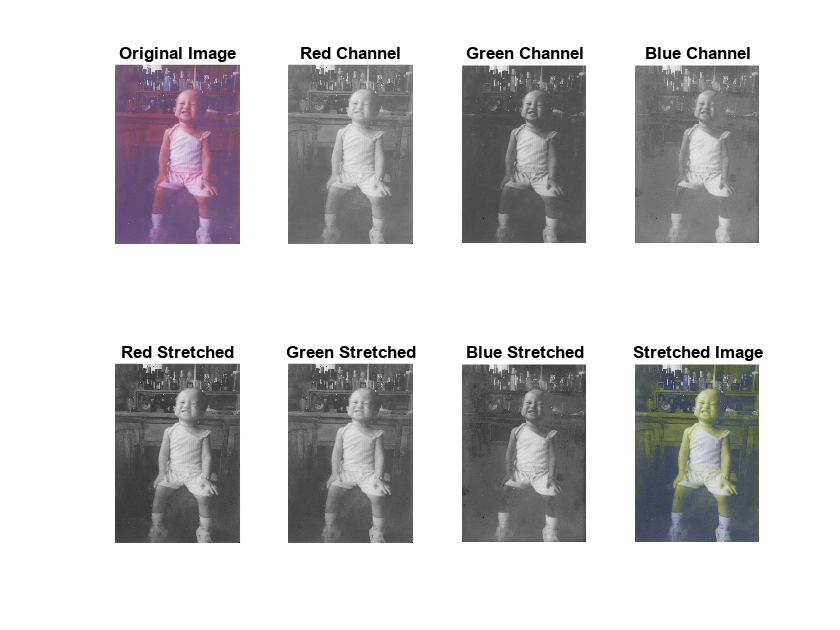

subplot(2,4,5);
imshow(Rcontrast);
title('Red Stretched');
subplot(2,4,6);
imshow(Gcontrast);
title('Green Stretched');
subplot(2,4,7);
imshow(Bcontrast);
title('Blue Stretched');
subplot(2,4,8);
imshow(I_restored);
title('Stretched Image')

#### Gray World Algorithm

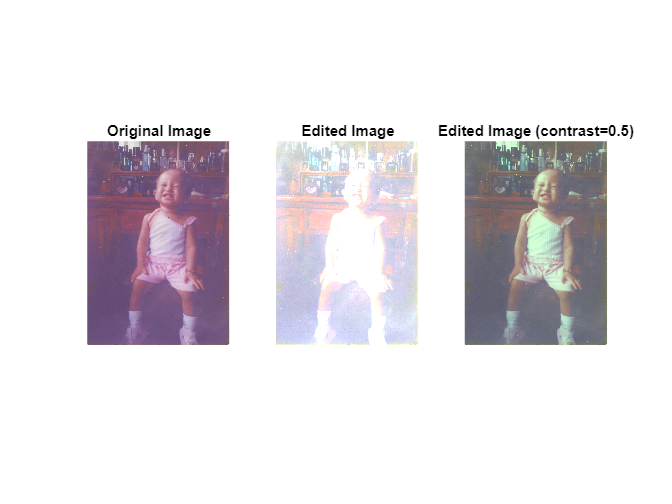

clear 
Inew = imread("janen.jpg");
R = double(Inew(:,:,1));
G = double(Inew(:,:,2));
B = double(Inew(:,:,3));

Rave = double(mean2(R));
Bave = double(mean2(B));
Gave = double(mean2(G));

Rwb = R./Rave;
Gwb = G./Gave;
Bwb = B./Bave;

I_restored(:,:,1) = Rwb;
I_restored(:,:,2) = Gwb;
I_restored(:,:,3) = Bwb;

subplot(1,3,1), imshow(Inew); title('Original Image');
subplot(1,3,2),imshow(I_restored); title('Edited Image');
subplot(1,3,3); imshow(I_restored*0.5); title('Edited Image (contrast=0.5)');

## White Patch Algorithm 

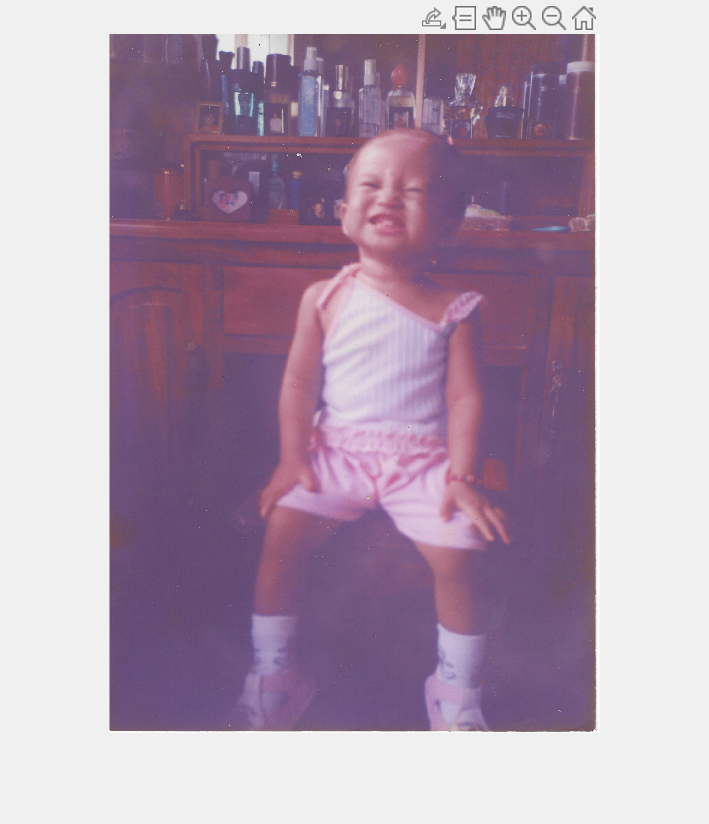

clear
Inew = imread("janen.jpg");
R = double(Inew(:,:,1));
G = double(Inew(:,:,2));
B = double(Inew(:,:,3));

region1 = imcrop(Inew);

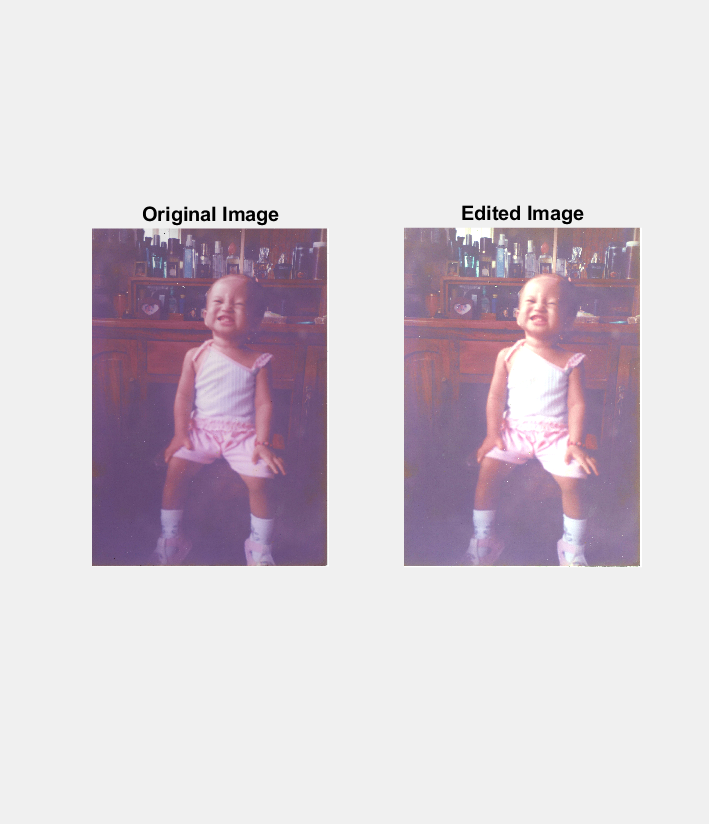


WR = double(region1(:,:,1));
WG = double(region1(:,:,2));
WB = double(region1(:,:,3)); 

WRave = double(mean2(WR));
WGave = double(mean2(WG));
WBave = double(mean2(WB));

Rwb = R./WRave;
Gwb = G./WGave;
Bwb = B./WBave;

I_restored(:,:,1) = Rwb;
I_restored(:,:,2) = Gwb;
I_restored(:,:,3) = Bwb;

subplot(1,2,1); 
imshow(Inew);
title('Original Image');
subplot(1,2,2);
imshow(I_restored);
title('Edited Image');